Theorie Bandpass Sampling: 

Sampelt man ein Signal mit einer Abtastfrequen fs, ist das das Gleich wie wenn man das Signal mit einer 

Folge von Dirac Impulsen falten würde:

oder einfach elementweise multiplizieren würde: 

signal=[1 1 1 1 2 2 2 2 ]

signal =      1     1     1     1     2     2     2     2


%impulskamm=[1]
impulskamm=[1 1 1 1 1 1 1 1]

impulskamm =      1     1     1     1     1     1     1     1


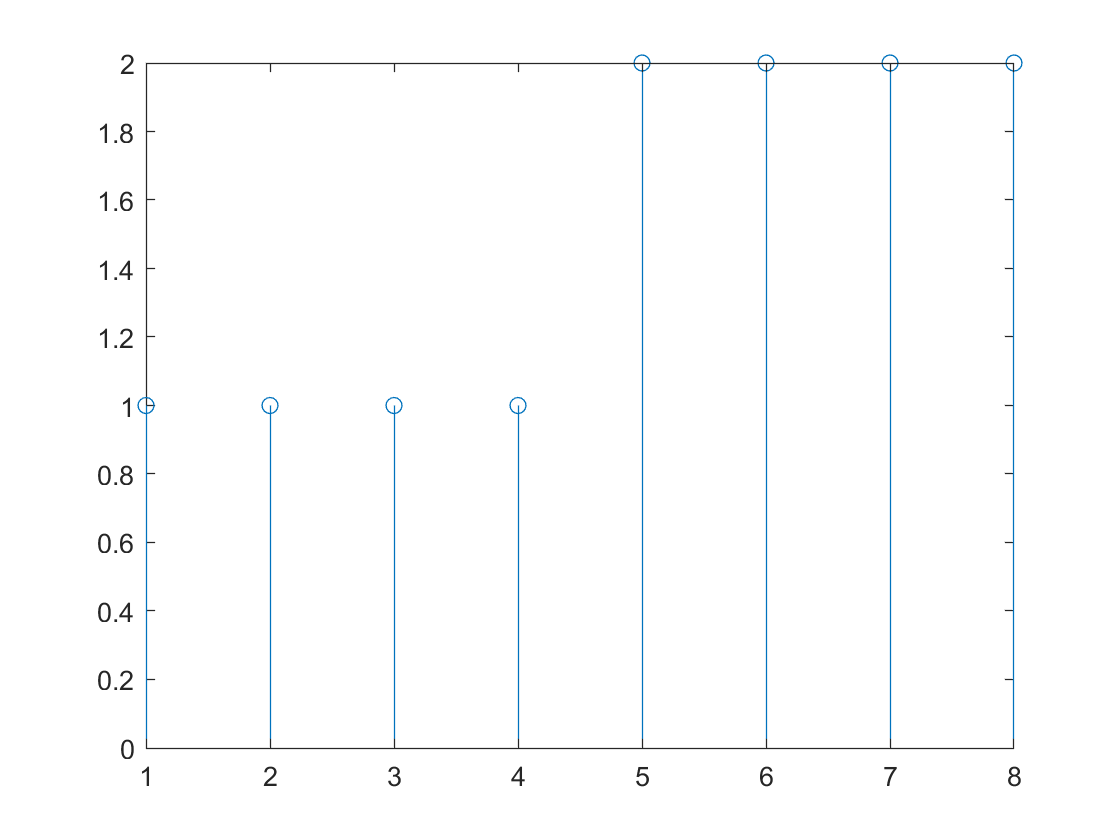

%stem(conv(signal,impulskamm))
stem(signal.*impulskamm)

signal=signal.*impulskamm;




Man erhält eine Folge von gewichteten Dirac Impulsen. Als nächstes wird diese Folge von Dirac Impulsen

in eine Fourierreihe Umgewandelt.

for n = 1:length(impulskamm)
    kreiskamm(n)=(signal(n)*exp(i*2*pi*n/length(impulskamm))) 
end

kreiskamm =    0.7071 + 0.7071i   0.0000 + 1.0000i  -0.7071 + 0.7071i  -1.0000 + 0.0000i  -1.4142 - 1.4142i  -0.0000 - 2.0000i   1.4142 - 1.4142i   0.0000 + 0.0000i


kreiskamm =    0.7071 + 0.7071i   0.0000 + 1.0000i  -0.7071 + 0.7071i  -1.0000 + 0.0000i  -1.4142 - 1.4142i  -0.0000 - 2.0000i   1.4142 - 1.4142i   0.0000 + 0.0000i


kreiskamm =    0.7071 + 0.7071i   0.0000 + 1.0000i  -0.7071 + 0.7071i  -1.0000 + 0.0000i  -1.4142 - 1.4142i  -0.0000 - 2.0000i   1.4142 - 1.4142i   0.0000 + 0.0000i


kreiskamm =    0.7071 + 0.7071i   0.0000 + 1.0000i  -0.7071 + 0.7071i  -1.0000 + 0.0000i  -1.4142 - 1.4142i  -0.0000 - 2.0000i   1.4142 - 1.4142i   0.0000 + 0.0000i


kreiskamm =    0.7071 + 0.7071i   0.0000 + 1.0000i  -0.7071 + 0.7071i  -1.0000 + 0.0000i  -1.4142 - 1.4142i  -0.0000 - 2.0000i   1.4142 - 1.4142i   0.0000 + 0.0000i


kreiskamm =    0.7071 + 0.7071i   0.0000 + 1.0000i  -0.7071 + 0.7071i  -1.0000 + 0.0000i  -1.4142 - 1.4142i  -0.0000 - 2.0000i   1.4142 - 1.4142i   0.0000 + 0.0000i


kreiskamm =    0.7071 + 0.7071i   0.0000 + 1.0000i  -0.7071 + 0.7071i  -1.0000 + 0.0000i  -1.4142 - 1.4142i  -0.0000 - 2.0000i   1.4142 - 1.4142i   0.0000 + 0.0000i


kreiskamm =    0.7071 + 0.7071i   0.0000 + 1.0000i  -0.7071 + 0.7071i  -1.0000 + 0.0000i  -1.4142 - 1.4142i  -0.0000 - 2.0000i   1.4142 - 1.4142i   2.0000 - 0.0000i


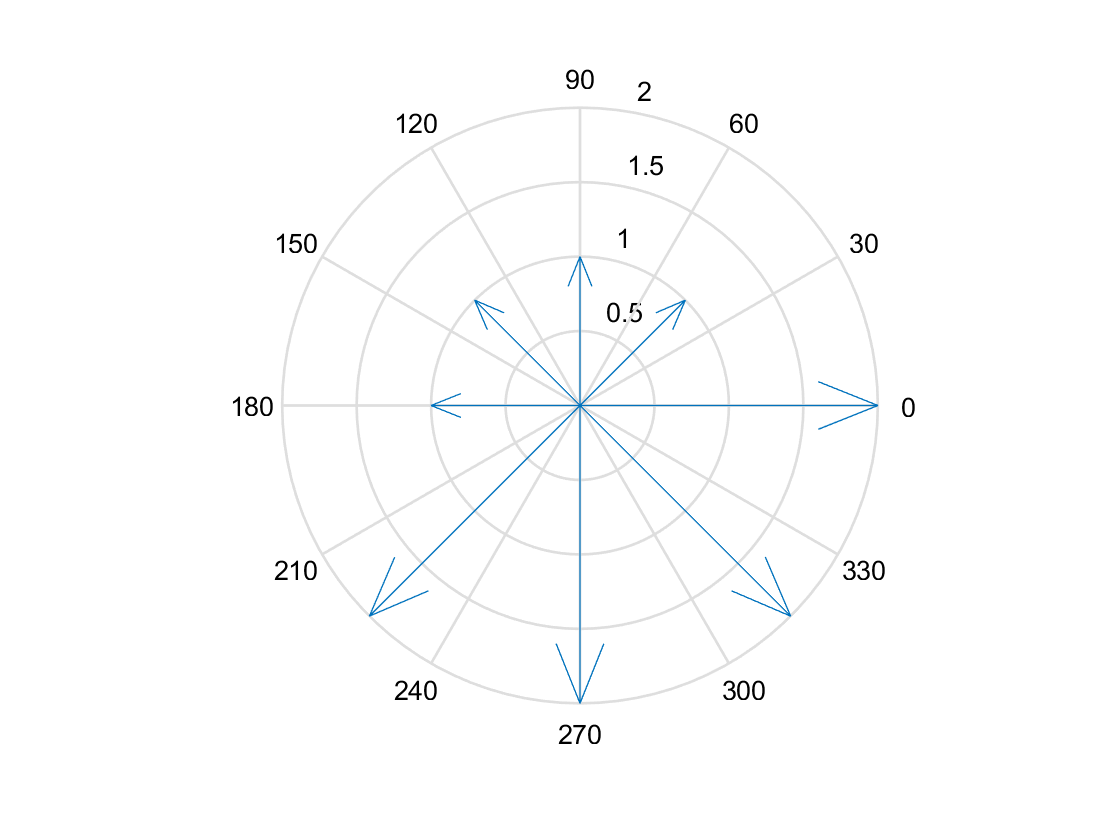

compass(kreiskamm)

was das genau bringt bin ich mir auch nichtmehr sicher, aber aus dieser Formel kann man herauslesen weshalb 

es spiegelspektren gibt

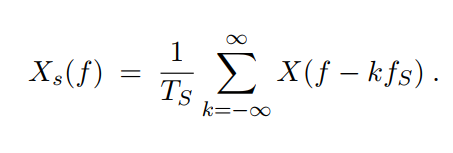

Da k von minus unendlich bis plus unendlich geht, wird das frequenzspektrum von X(f) irgendwie immer repetiert

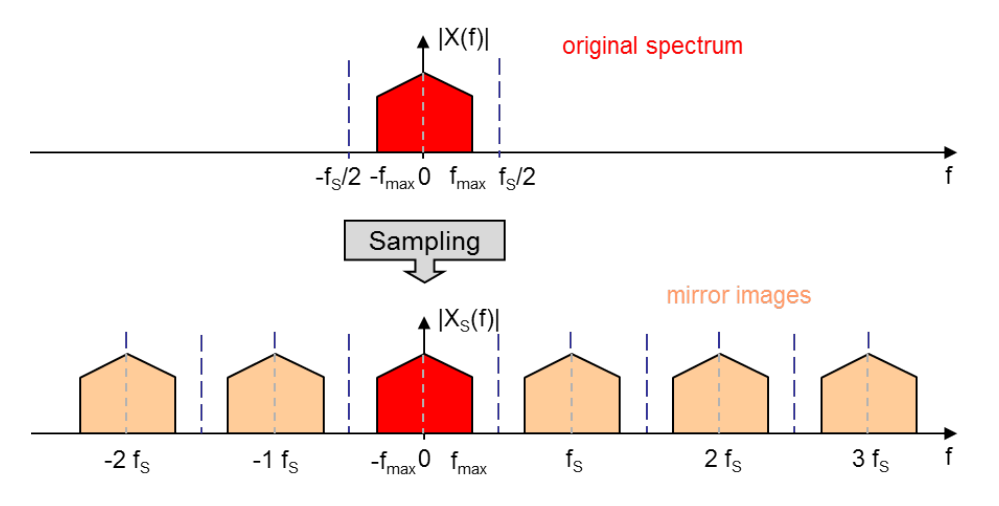

- Das Frequenzband ist geht bis fs/2

- fs ist die abtastfrequenz und muss einfach grösser als doppelt so gross sein wie f_max

- fs=1/Ts, wird abtastung bestimmt und umgekehrt je nach aufgabe

Durch geschicktes Sampeln, kann man jetzt diesen Effekt des Spiegelns ausnutzen!

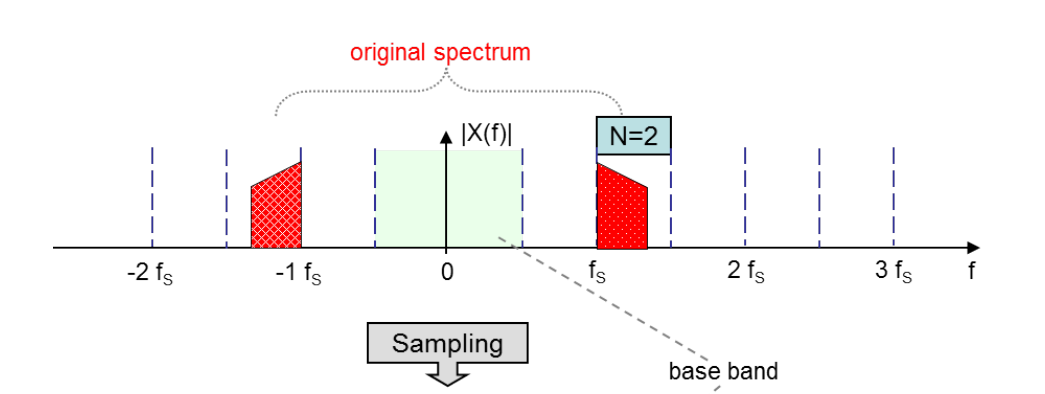

Um dieses Signal korrekt abzutasten, müsste ich ja mit mindestens 2fs abtasten, angenommen ich könnte das nicht. 

Was wäre eine Alternative? Wenn ich jetzt mit **fs **abtaste erhalte ich folgendes Spektrum:

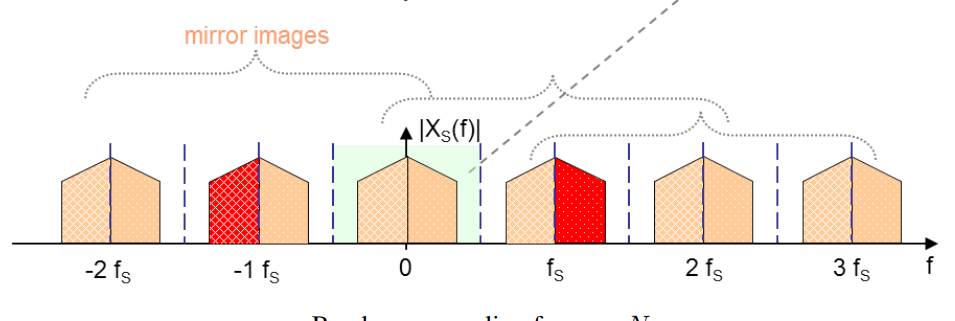

[y,Fs] = audioread("summen2.wav")
sig=y(:,1)';
sig=downsample(sig,40)
t=0:length(sig)-1;

stem(t,sig)
S=fft(sig)
stem(abs(S))
plot(fftshift(abs(S)))